clear all
syms a_0 a_1 a_2 a_3 b_0 b_1 c_0 c_1 c_2 c_3
syms q_p q_k v
syms t_a t_c t_k t_b
syms dq_k dq_p

t_c = t_k-t_b;

A = a_0 - q_p;

B = a_1 - dq_p;

C = a_0 + a_1*t_a + a_2*(t_a)^2 + a_3*(t_a)^3 - b_0 - b_1*t_a;

D = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - b_1;

E = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2;

F = b_1 - v;

G = b_0 + b_1*t_c - c_0 - c_1*t_c - c_2*(t_c)^2 - c_3*(t_c)^3;
 
H = b_1 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2;

I = c_0 + c_1*t_k + c_2*(t_k)^2 + c_3*(t_k)^3 -q_k;

J = c_1 + 2*c_2*t_k + 3*c_3*(t_k)^2 - dq_k;

[Z] = solve(A==0, B==0, C==0, D==0, E==0, F==0, G==0, H==0, I==0, J==0 ,a_0, a_1, a_2, a_3, b_0, b_1, c_0, c_1, c_2, c_3);

solved = Z;
q_p_1 = 0;
dq_p_1 = 0.1;
q_k_1 = 1/2 * pi;
dq_k_1 = 0.1;
Tk_1 = 10;
Ta_1 = 4;
Tb_1 = 4;
dt_1 = 0.01;
V_1 = 0.2;
[q_1,dq_1,ddq_1, t_1] = Trajectory_Generation(solved, q_p_1, dq_p_1, q_k_1, dq_k_1, Tk_1, Ta_1, Tb_1, dt_1, V_1);

solved = Z;
q_p_2 = 0;
dq_p_2 = 0.2;
q_k_2 = 3/2 * pi;
dq_k_2 = 0.1;
Tk_2 = 10;
Ta_2 = 2;
Tb_2 = 4;
dt_2 = 0.01;
V_2 = 0.5;
[q_2,dq_2,ddq_2, t_2] = Trajectory_Generation(solved, q_p_2, dq_p_2, q_k_2, dq_k_2, Tk_2, Ta_2, Tb_2, dt_2, V_2);


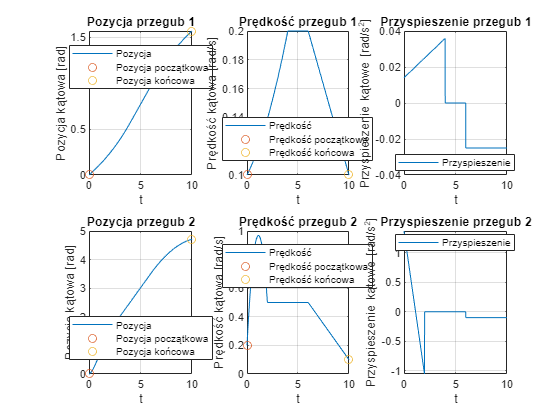

figure;
subplot(2, 3, 1);
plot(t_1, q_1, t_1(1), q_p_1, 'o', Tk_1, q_k_1, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 1')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 3, 2);
plot(t_1, dq_1, t_1(1), dq_p_1, 'o', Tk_1, dq_k_1, 'o')
legend('Prędkość', 'Prędkość początkowa', 'Prędkość końcowa', "Location","best")
title('Prędkość przegub 1')
xlabel('t')
ylabel('Prędkość kątowa [rad/s]')
grid on
axis auto

subplot(2, 3, 3);
plot(t_1, ddq_1)
legend('Przyspieszenie', "Location","best")
title('Przyspieszenie przegub 1')
xlabel('t')
ylabel('Przyspieszenie kątowe [rad/s{^2}]')
grid on
axis auto

subplot(2, 3, 4);
plot(t_2, q_2, t_2(1), q_p_2, 'o', Tk_2, q_k_2, 'o')
legend('Pozycja', 'Pozycja początkowa', 'Pozycja końcowa', "Location","best")
title('Pozycja przegub 2')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(2, 3, 5);
plot(t_2, dq_2, t_2(1), dq_p_2, 'o', Tk_2, dq_k_2, 'o')
legend('Prędkość', 'Prędkość początkowa', 'Prędkość końcowa', "Location","best")
title('Prędkość przegub 2')
xlabel('t')
ylabel('Prędkość kątowa [rad/s]')
grid on
axis auto

subplot(2, 3, 6);
plot(t_2, ddq_2)
legend('Przyspieszenie', "Location","best")
title('Przyspieszenie przegub 2')
xlabel('t')
ylabel('Przyspieszenie kątowe [rad/s{^2}]')
grid on
axis auto

t = t_1;
q = double([q_1; q_2]');
dq = double([dq_1; dq_2]');
L1 = 0.6;
L2 = 0.5;
[Pee, Psiee, Vee, Omee] = direct_2DoF(q, dq, L1, L2);

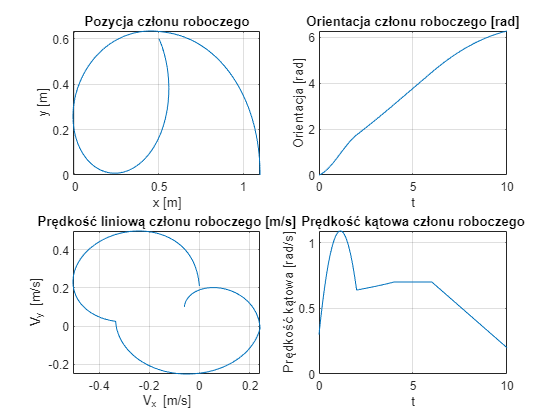

figure
subplot(2, 2, 1)
plot(Pee(:, 1), Pee(:, 2))
title('Pozycja członu roboczego')
xlabel('x [m]')
ylabel('y [m]')
grid on
axis auto

subplot(2, 2, 2)
plot(t, Psiee)
title('Orientacja członu roboczego [rad]')
xlabel('t')
ylabel('Orientacja [rad]')
grid on
axis auto

subplot(2, 2, 3)
plot(Vee(:, 1), Vee(:, 2))
title('Prędkość liniową członu roboczego [m/s]')
xlabel('V{_x} [m/s]')
ylabel('V{_y} [m/s]')
grid on
axis auto

subplot(2, 2, 4)
plot(t, Omee)
title('Prędkość kątowa członu roboczego')
xlabel('t')
ylabel('Prędkość kątowa [rad/s]')
grid on
axis auto

[sol1, sol2] = inverse_2DoF(Pee, L1, L2);

figure
subplot(5, 1, 1)
plot(Pee(:, 1), Pee(:, 2))
title('Pozycja członu roboczego')
xlabel('x [m]')
ylabel('y [m]')
grid on
axis auto

subplot(5, 1, 2)
plot(t, sol1(:, 1))

title('Pozycja kątowa przegubu 1 (rozwiązanie 1)')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(5, 1, 3)
plot(t, sol1(:, 2))

title('Pozycja kątowa przegubu 2 (rozwiązanie 1)')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(5, 1, 4)
plot(t, sol2(:, 1))

title('Pozycja kątowa przegubu 1 (rozwiązanie 2)')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

subplot(5, 1, 5)
plot(t, sol2(:, 2))

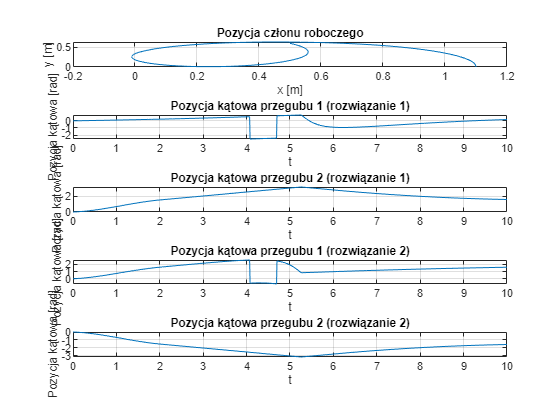

title('Pozycja kątowa przegubu 2 (rozwiązanie 2)')
xlabel('t')
ylabel('Pozycja kątowa [rad]')
grid on
axis auto

function [q,dq,ddq, t] = Trajectory_Generation(solved, q_p_in,dq_p_in,q_k_in,dq_k_in,Tk_in,Ta_in,Tb_in,dt_in,V_in)
    syms q_p q_k v
    syms t_a t_c t_k t_b
    syms dq_k dq_p
    temp = struct2cell(solved);
    val = subs(temp,{q_p, dq_p, q_k, dq_k, t_k, t_a, t_b, v},{q_p_in dq_p_in q_k_in dq_k_in Tk_in Ta_in Tb_in V_in});
    t1 = 0:dt_in:Ta_in;
    q_1 = val(1) + val(2) * t1 + val(3) * (t1).^2 + val(4) * (t1).^3;
    d_q1 = val(2) + 2*val(3)*t1 + 3*val(4) * (t1).^2;
    dd_q1 = 2*val(3) + 6*val(4)*t1;
    
    t2 = Ta_in:dt_in:(Tk_in - Tb_in);
    q_2 = val(5) + val(6) * t2;
    d_q2 = val(6) + zeros(1, length(t2));
    dd_q2 = zeros(1, length(t2));
    
    t3 = (Tk_in - Tb_in):dt_in:Tk_in;
    q_3 = val(7) + val(8) * t3 + val(9) * (t3).^2 + val(10) * (t3).^3;
    d_q3 = val(8) + 2*val(9)*t3 + 3*val(10) * (t3).^2;
    dd_q3 = 2*val(9) + 6*val(10)*t3;

    t = [0:dt_in:Tk_in];
    q = [q_1(1:end-1), q_2(1:end-1), q_3];
    dq = [d_q1(1:end-1), d_q2(1:end-1), d_q3];
    ddq = [dd_q1(1:end-1), dd_q2(1:end-1), dd_q3];
end

function [Pee, Psiee, Vee, Omee] = direct_2DoF(q, dq, L1, L2)

%   q – dwuelementowy wektor zawierający pozycje kątowe przegubów [rad]
%   dq – dwuelementowy wektor zawierający prędkości kątowe przegubów[rad/s].
%   L1, L2 – długości członów manipulatora [m]
%   Pee – dwuelementowy wektor zawierający składową X i składową Y pozycji członu roboczego [m].
%   Psiee – orientacja członu roboczego [rad].
%   Vee – dwuelementowy wektor zawierający prędkość liniową członu roboczego [m/s]
%   Omee – prędkość kątowa członu roboczego [rad/s].
    Pee = [cos(q(:, 1)) .* L1 + cos(q(:,1) + q(:,2)) .* L2, sin(q(:,1)) .* L1 + sin(q(:,1) + q(:,2)) .* L2];
    Psiee = q(:,1) + q(:,2);
    Vee = [-L1 .* sin(q(:,1)) .* dq(:,1) - L2 .* sin(q(:,1)+q(:,2)).*(dq(:,1)+dq(:,2)), ...
        L1 .* cos(q(:,1)) .* dq(:,1) + L2 .* cos(q(:,1) + q(:,2)) .* (dq(:,1) + dq(:,2))];
    Omee = dq(:,1) + dq(:,2);
end

function [sol_1, sol_2] = inverse_2DoF(Pee, L1, L2)
    
%     Pee – dwuelementowy wektor zawierający składową X i składową Y pozycji członu roboczego [m].
%     L1, L2 – długości członów manipulatora [m].
%     sol_1, sol_2 – dwuelementowe wektory zawierające pozycje kątowe przegubów [rad].

    sol_1_theta_2 = acos((Pee(:, 1).^2 + Pee(:, 2).^2 - L1^2 - L2^2) / (2*L1*L2));
    sol_1_theta_1 = atan((Pee(:, 2)./Pee(:, 1))) - atan(L2.*sin(sol_1_theta_2)./(L1 + L2 .* cos(sol_1_theta_2)));
    sol_1 = [sol_1_theta_1, sol_1_theta_2];
    
    sol_2_theta_2 = -acos((Pee(:, 1).^2 + Pee(:, 2).^2 - L1^2 - L2^2) / (2*L1*L2));
    sol_2_theta_1 = atan((Pee(:, 2)./ Pee(:, 1))) - atan((L2.*sin(sol_2_theta_2)) ./ (L1 + (L2 .* cos(sol_2_theta_2))));
    sol_2 = [sol_2_theta_1, sol_2_theta_2];
    
end
